Prob4


[y,Fs] = audioread("speech.wav")

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Fs = 16000

sound(y,Fs)
z=size(y)

z =        19120           1


F = 250*a

F = 500

Y = y *cos(2*pi*F/Fs)

Y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


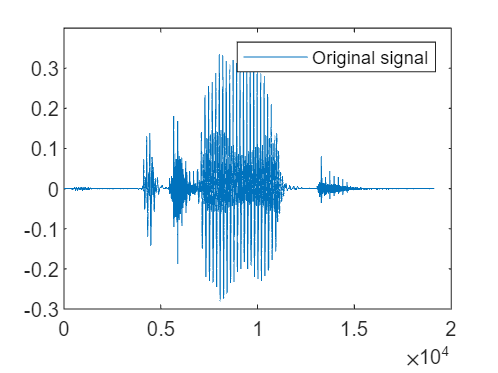

sound(y,Fs)
figure; plot(y) ; legend("Original signal") 

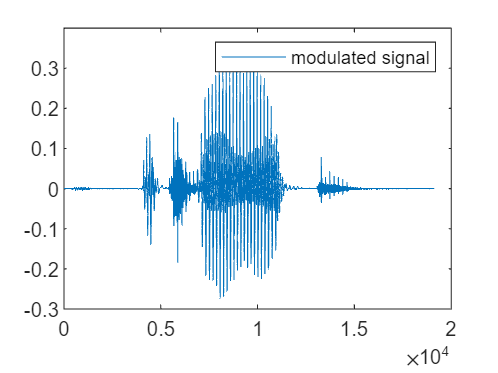

figure; plot(Y) ; legend("modulated signal")

Fy = fft(y) 

Fy = 1.0e+02 *

   0.3704 + 0.0000i
  -0.2912 - 0.0933i
   0.1662 + 0.0740i
  -0.1196 - 0.0416i
   0.0800 + 0.0614i
   0.0022 - 0.0479i
  -0.0223 - 0.0201i
  -0.0280 + 0.0329i
   0.0421 + 0.0178i
  -0.0045 - 0.0350i


FY = fft(Y)

FY = 1.0e+02 *

   0.3632 + 0.0000i
  -0.2856 - 0.0915i
   0.1630 + 0.0725i
  -0.1173 - 0.0408i
   0.0785 + 0.0602i
   0.0022 - 0.0470i
  -0.0219 - 0.0197i
  -0.0275 + 0.0323i
   0.0413 + 0.0175i
  -0.0044 - 0.0344i


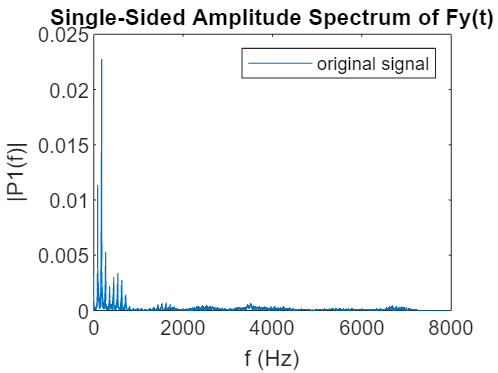

 %plotting fft of original                           
T = 1/Fs;             % Sampling period       
L = z(1);             % Length of signal
t = (0:L-1)*T;    % Time vector
P2 = abs(Fy/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title("Single-Sided Amplitude Spectrum of Fy(t)")
legend("original signal")
xlabel("f (Hz)")
ylabel("|P1(f)|")

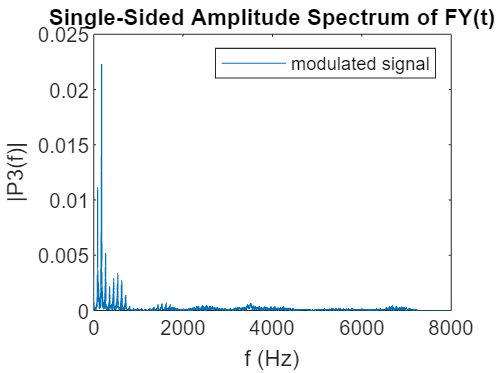

%plotting fft of modulated
T = 1/Fs;             % Sampling period       
L = z(1);             % Length of signal
t = (0:L-1)*T;    % Time vector
P4 = abs(FY/L);
P3 = P4(1:L/2+1);
P3(2:end-1) = 2*P3(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P3) 
title("Single-Sided Amplitude Spectrum of FY(t)")
legend("modulated signal")
xlabel("f (Hz)")
ylabel("|P3(f)|")